clc;
clear;
path = "C:\Users\AVISH\OneDrive\Desktop\Data_Lab3\Group\imu.csv";
data = readtable(path,VariableNamingRule="preserve");
header_sec = data.("header.stamp.secs");
header_nsec = data.("header.stamp.nsecs")/(10^9); %convert nano seconds to secs
time = header_sec+header_nsec;
t = time-min(time);


%% GYRO
gx = data.("IMU.angular_velocity.x");
gy = data.("IMU.angular_velocity.y");
gz = data.("IMU.angular_velocity.z");

%% ACCELERATION
ax = data.("IMU.linear_acceleration.x");
ay = data.("IMU.linear_acceleration.y");
az = data.("IMU.linear_acceleration.z");

%% ORIENTATION
qx = data.("IMU.orientation.x");
qy = data.("IMU.orientation.y");
qz = data.("IMU.orientation.z");
qw = data.("IMU.orientation.w");

%convert back from quaternion to euler
q= [qw,qx,qy,qz];
euler=rad2deg(quat2eul(q));
yaw = euler(:,1);
pitch = euler(:,2);
roll = euler(:,3);

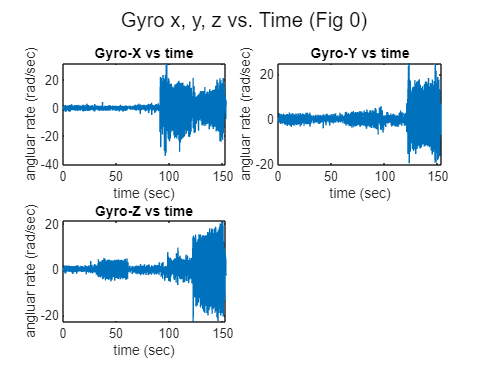

% Plot gyro x,y,z vs time
figure();
sgtitle("Gyro x, y, z vs. Time (Fig 0)");
subplot(2,2,1);
plotvstime(gx,t,'angluar rate (rad/sec)','Gyro-X vs time')
subplot(2,2,2);
plotvstime(gy,t,'angluar rate (rad/sec)','Gyro-Y vs time')
subplot(2,2,3);
plotvstime(gz,t,'angluar rate (rad/sec)','Gyro-Z vs time')

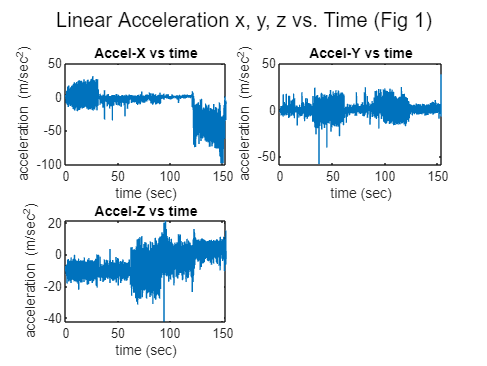


% Plot accel x,y,z vs time
figure();
sgtitle("Linear Acceleration x, y, z vs. Time (Fig 1)");
subplot(2,2,1);
plotvstime(ax,t,'acceleration (m/sec^2)','Accel-X vs time')
subplot(2,2,2);
plotvstime(ay,t,'acceleration (m/sec^2)','Accel-Y vs time')
subplot(2,2,3);
plotvstime(az,t,'acceleration (m/sec^2)','Accel-Z vs time')

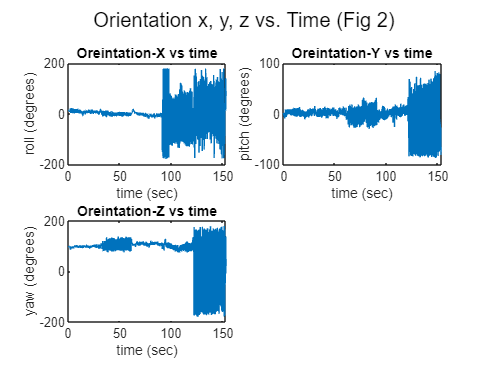



% Plot oreintation x,y,z vs time
figure();
sgtitle("Orientation x, y, z vs. Time (Fig 2)");
subplot(2,2,1);
plotvstime(roll,t,'roll (degrees)','Oreintation-X vs time')
subplot(2,2,2);
plotvstime(pitch,t,'pitch (degrees)','Oreintation-Y vs time')
subplot(2,2,3);
plotvstime(yaw,t,'yaw (degrees)','Oreintation-Z vs time')

## Activity 1 - Motion along x-axis

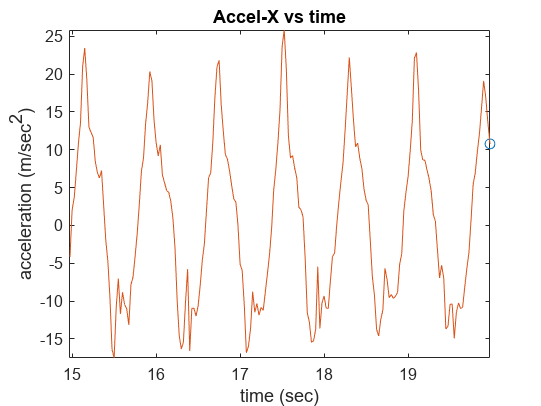

ax1=ax(15*40:20*40);
ay1=ay(15*40:20*40);
az1=az(15*40:20*40);
t1 = t(15*40:20*40);

%Plot animated graphs
ani_plot(ax1,t1,'acceleration (m/sec^2)','Accel-X vs time')

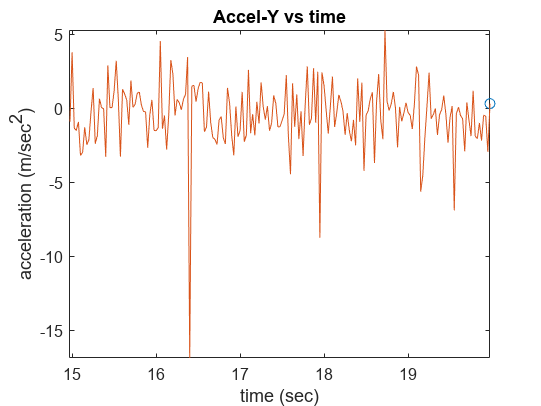

ani_plot(ay1,t1,'acceleration (m/sec^2)','Accel-Y vs time')

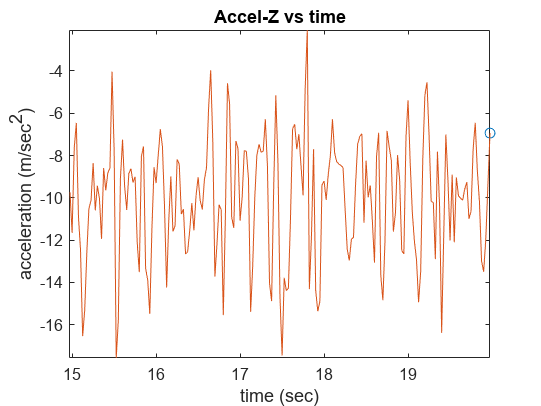

ani_plot(az1,t1,'acceleration (m/sec^2)','Accel-Z vs time')

## Activity 2 - Rotation about X axis

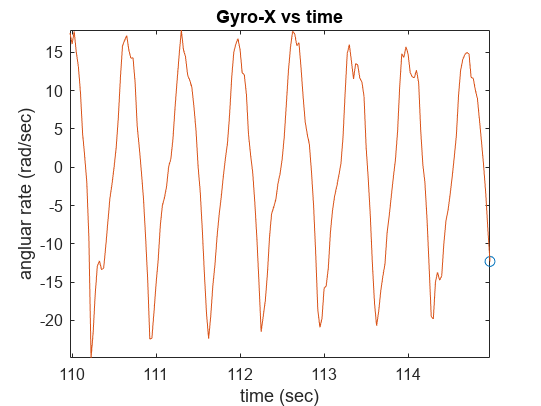

gx2=gx(110*40:115*40);
gy2=gy(110*40:115*40);
gz2=gz(110*40:115*40);
t2 = t(110*40:115*40);

%Plot animated graphs
ani_plot(gx2,t2,'angluar rate (rad/sec)','Gyro-X vs time')

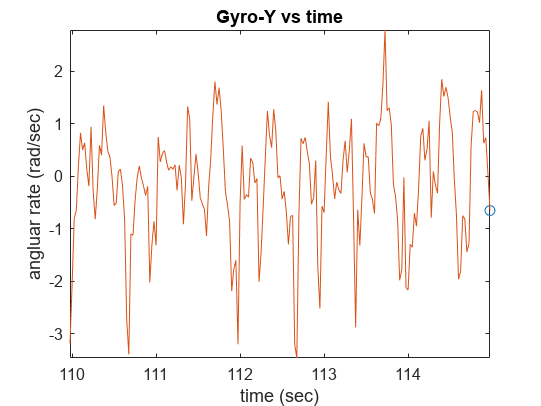

ani_plot(gy2,t2,'angluar rate (rad/sec)','Gyro-Y vs time')

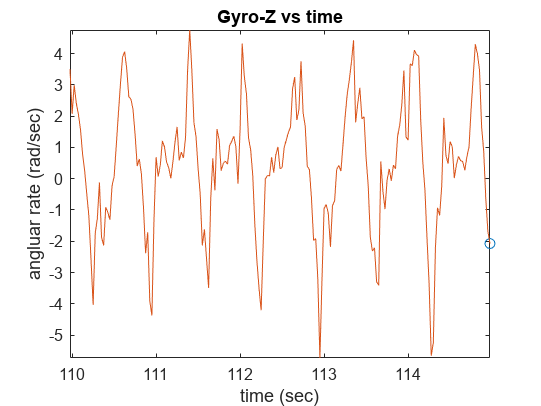

ani_plot(gz2,t2,'angluar rate (rad/sec)','Gyro-Z vs time')

## Activity 3 - Random Uniform Motion

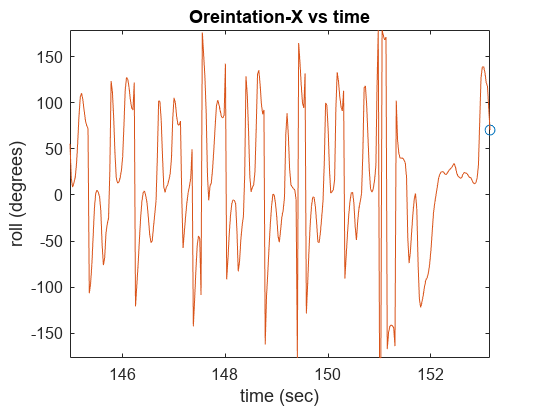

ox3=roll(145*40:end);
oy3=pitch(145*40:end);
oz3=yaw(145*40:end);
t3 = t(145*40:end);

%Plot animated graphs
ani_plot(ox3,t3,'roll (degrees)','Oreintation-X vs time')

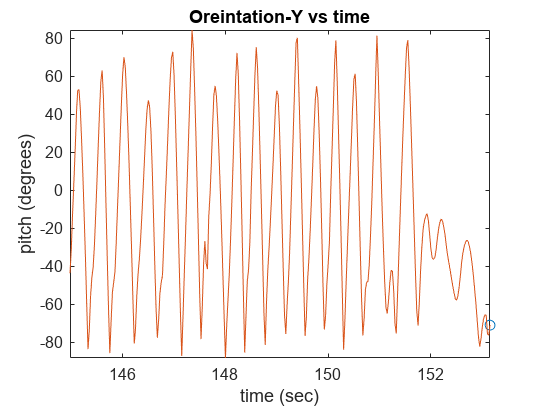

ani_plot(oy3,t3,'pitch (degrees)','Oreintation-Y vs time')

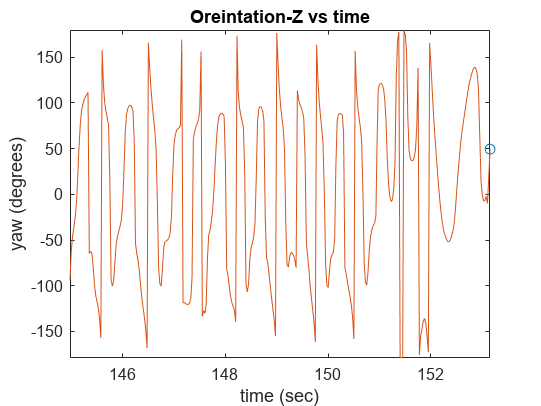

ani_plot(oz3,t3,'yaw (degrees)','Oreintation-Z vs time')

function plotvstime(omega,time,Ylabel,Title)
% function to plot signal vs time
plot(time,omega)
xlabel('time (sec)')
ylabel(Ylabel)
title(Title)
%xlim([0 max(time)])
end

function ani_plot(omega,time,Ylabel,Title)
% function to plot signal in animated form
figure();
for i = 1:length(time)
    plot(time(i),omega(i),'o')
    hold on
    plot(time(1:i),omega(1:i))
    xlabel('time (sec)')
    ylabel(Ylabel)
    title(Title)
    axis([min(time),max(time),min(omega),max(omega)])
    pause(1/40)
     if i~= length(time)
         clf
     end
end
end
